# **WM9QE: Applied Statistics for Artificial Intelligence**

**Non-Linear Regression **

This live script includes the examples provided in week 3 for **Non-Linear Regression**. Full detail of the lectures and examples are availabe on the Moodle page here [Section: Week Three | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=621569)

**Learning Objectives:** By the end of this session, you will be able to:

- Identify when a relationship between variables is **non-linear**.

- Fit, interpret, and evaluate **non-linear models** in MATLAB.

- Understand and apply **logistic regression** for binary outcomes.

- Assess **model fit**, **residuals**, and **predictive accuracy**.

# Example Quadratic Regression (Investment → Revenue)

**Learning Objectives:** This live section is designed for you to practice: 

- How to decide between linear vs non-linear models using visuals + diagnostics 

- How to fit multiple candidate models (linear, quadratic, cubic, log, exp, power) 

- How to evaluate with R², Adjusted R², ANOVA, p-values 

- How to test assumptions on residuals: normality, constant variance, independence 

- How to make predictions with uncertainty (confidence & prediction intervals)

**Why this matters:** 

- Marketing ROI curves often show diminishing returns (curvature) → quadratic/log/power helpful 

- Operations & growth processes often exhibit exponential/power behavior 

- AI decision support systems must quantify uncertainty and check validity of model assumptions

**Summary of the MATLAB Functions Used in this Session**

## Step 0. Initialisation

clc; clear; close all; 

## Step 1. Input Data

Data describe an investment budget (x) vs revenue (y). We will walk through a **complete non-linear regression workflow**.

Investment = [1685,1465,2143,1165,1132,1785,2001,1878,1509,1282,1218,1568,...
              1947,1683,1655,1382,1815,1003,1085,1930,1935,2158,1424,2063]';
Revenue    = [17017,16876,19256,16733,17105,17538,18386,17804,17047,17214,...
              17059,17659,17855,17756,17655,16661,18158,16608,16689,18172,...
              18674,18958,17374,18783]';

Data = table(Investment, Revenue)

Data = 24×2 table
    Investment    Revenue
    __________    _______

       1685        17017 
       1465        16876 
       2143        19256 
       1165        16733 
       1132        17105 
       1785        17538 
       2001        18386 
       1878        17804 
       1509        17047 
       1282        17214 
       1218        17059 
       1568        17659 
       1947        17855 
       1683        17756 
       1655        17655 
       1382        16661 



% Quick descriptive stats — MATLAB "summary" formats table summaries
summary(Data)


Data: 24×2 table

Variables:

    Investment: double
    Revenue: double

Statistics for applicable variables:

                  NumMissing       Min           Median           Max            Mean             Std     

    Investment        0            1003              1669         2158        1.6213e+03        353.2379  
    Revenue           0           16608        1.7596e+04        19256        1.7627e+04        776.7064  




% Convenience scalars
n  = height(Data);
mX = mean(Investment); 
sX = std(Investment);
mY = mean(Revenue);    
sY = std(Revenue);

## Step 2. Choose Regression Model: Visual inspection (Linearity vs Nonlinearity)

We start by checking whether a straight line is plausible. Visual checks we will do: 

- Scatter plot, linear or non-linear visual checks.

- Direction check (monotonicity): Spearman correlation 

- Extreme values: look for unusual points 

- Homoskedasticity (same variance): initial visual check (funnel shape?) 

- Monotonicity: do higher x generally imply higher y? (not required, but informative)

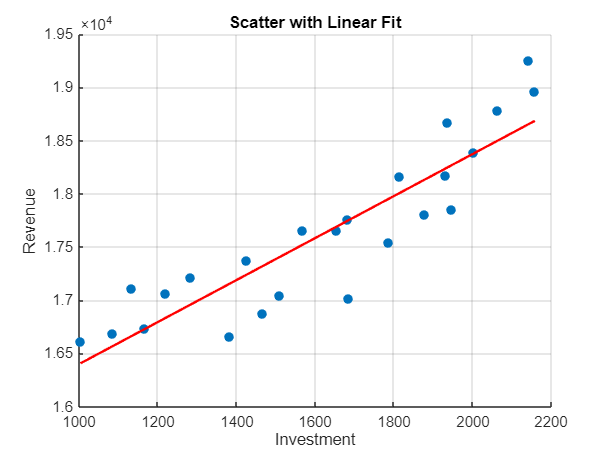

figure('Color','w'); 

% (a) Scatter with linear fit
scatter(Investment, Revenue, 40, 'filled'); grid on; hold on;
p1 = polyfit(Investment, Revenue, 1);       % polyfit(x,y,1): linear least squares line
xfit = linspace(min(Investment), max(Investment), 200)';
yfit_lin = polyval(p1, xfit);               % polyval(p1,x): evaluate polynomial at x
plot(xfit, yfit_lin, 'r-', 'LineWidth', 1.6);
xlabel('Investment'); ylabel('Revenue');
title('Scatter with Linear Fit');



% (b) Direction / monotonicity check using Spearman correlation (Optional)
% corr(x,y,'Type','Spearman'): rank-based correlation, robust for monotonic trends
[rho_spearman, p_spearman] = corr(Investment, Revenue, 'Type','Spearman');

fprintf('\nDirection/Monotonicity (Spearman): rho=%.3f, p=%.4f\n', rho_spearman, p_spearman);


Direction/Monotonicity (Spearman): rho=0.900, p=0.0000


if p_spearman < 0.05
    fprintf('→ Evidence of a monotonic relationship (not necessarily linear).\n');
else
    fprintf('→ No strong evidence of monotonicity.\n');
end

→ Evidence of a monotonic relationship (not necessarily linear).


## Step 3. Fit Candidate Models and Compute R², Adjusted R²

Fit multiple candidate regression models & compare (Model Selection Stage)

**Purpose:**We do not assume quadratic straight away, we TEST several plausible nonlinear models.

Candidate models:

We will compare $R^2$and $\textrm{Adjusted}\;R^2$

$R^2$** (Coefficient of Determination): **Measures how much of the variability in **y** is explained by the model:


$$R^2 =1-\frac{{\textrm{SS}}_{\textrm{res}} }{{\textrm{SS}}_{\textrm{tot}} }=1-\frac{\textrm{Unexplained}\;V\textrm{ariance}\;\left(\textrm{Residuals}\right)}{\textrm{Total}\;V\textrm{ariance}\;in\;t\textrm{he}\;D\textrm{ata}}$$


- Higher **R² ⇒ model explains more variation in y** ➜ sounds good… *but* R² always **increases** when we add more predictors, even useless ones.

- Adding more variables **always** increases R², even if the new variable has **no real relationship** with the response. So R² can **reward overfitting**

**Adjusted R², Fixes Overfitting: **Adjusted R² *penalises* model complexity:


$$\textrm{Adjusted}\;R^2 =1-\left(1-R^2 \right)\frac{n-1}{n-p-1}$$


- where $n$ is the number of observations and $p$ is the number of predictors (excluding intercept). It increases **only** if the new predictor *adds meaningful explanatory power*. Otherwise → **Adjusted R² decreases**, warning us about overfitting.

**Why is Adjusted R² important in AI and industry?**

% Model selection principle (Parsimony):
%  Choose the simplest model that explains the data well
%  Diagnostic checks must support validity (residuals, meaning of coefficients)

% Helper functions for R² and Adjusted R²
Rsq   = @(y,yhat) 1 - sum((y - yhat).^2) / sum((y - mean(y)).^2);
AdjR2 = @(R2,n,p) 1 - (1-R2)*(n-1)/(n-p-1);

%% 1️ Linear Model 
p_lin = polyfit(Investment, Revenue, 1);     % polyfit: polynomial regression coefficients
yhat_lin = polyval(p_lin, Investment);       % polyval: predicts y using polynomial coefficients
R2_lin  = Rsq(Revenue, yhat_lin);
Adj_lin = AdjR2(R2_lin, n, 1);
% Fitted equation:
eq_lin = sprintf('ŷ = %.3f + %.3f·x', p_lin(2), p_lin(1));

%% 2️ Quadratic Model 
p_quad = polyfit(Investment, Revenue, 2);
yhat_quad = polyval(p_quad, Investment);
R2_quad  = Rsq(Revenue, yhat_quad);
Adj_quad = AdjR2(R2_quad, n, 2);
eq_quad = sprintf('ŷ = %.3f + %.3f·x + %.6f·x²', p_quad(3), p_quad(2), p_quad(1));

%% 3️ Cubic Model 
p_cub = polyfit(Investment, Revenue, 3);
yhat_cub = polyval(p_cub, Investment);
R2_cub  = Rsq(Revenue, yhat_cub);
Adj_cub = AdjR2(R2_cub, n, 3);
eq_cub = sprintf('ŷ = %.3f + %.3f·x + %.6f·x² + %.9f·x³', ...
    p_cub(4), p_cub(3), p_cub(2), p_cub(1));

%% 4️ Logarithmic (Optional)
X_log  = [ones(n,1), log(Investment)];
b_log  = X_log \ Revenue;           % "\" does (X'X)^(-1)X'y — OLS regression
yhat_log = X_log * b_log;
R2_log  = Rsq(Revenue, yhat_log);
Adj_log = AdjR2(R2_log, n, 1);
eq_log = sprintf('ŷ = %.3f + %.3f·ln(x)', b_log(1), b_log(2));

%% 5️ Exponential (Optional)
lnY = log(Revenue);
X_exp = [ones(n,1), Investment];
c_exp = X_exp \ lnY;
yhat_exp = exp(X_exp * c_exp);
R2_exp  = Rsq(Revenue, yhat_exp);
Adj_exp = AdjR2(R2_exp, n, 1);
eq_exp = sprintf('ŷ = exp(%.3f + %.6f·x)', c_exp(1), c_exp(2));

%% 6 Power (Optional)
X_pow = [ones(n,1), log(Investment)];
d_pow = X_pow \ lnY;
yhat_pow = exp(X_pow * d_pow);
R2_pow  = Rsq(Revenue, yhat_pow);
Adj_pow = AdjR2(R2_pow, n, 1);
eq_pow = sprintf('ŷ = exp(%.3f)·x^(%.3f)', d_pow(1), d_pow(2));

%% Compare all model fitness values in one professional table
Model = ["Linear";"Quadratic";"Cubic";"Logarithmic";"Exponential";"Power"];
R2_vals    = [R2_lin; R2_quad; R2_cub; R2_log; R2_exp; R2_pow];
AdjR2_vals = [Adj_lin; Adj_quad; Adj_cub; Adj_log; Adj_exp; Adj_pow];
Equations  = {eq_lin; eq_quad; eq_cub; eq_log; eq_exp; eq_pow};

FitSummary = table(Model, R2_vals, AdjR2_vals, Equations)

FitSummary = 6×4 table
        Model        R2_vals    AdjR2_vals                             Equations                         
    _____________    _______    __________    ___________________________________________________________

    "Linear"           0.806     0.79718      {'ŷ = 14426.044 + 1.974·x'                                }
    "Quadratic"      0.87431     0.86234      {'ŷ = 18913.946 + -3.949·x + 0.001861·x²'                 }
    "Cubic"          0.88027     0.86231      {'ŷ = 12337.282 + 9.198·x + -0.006622·x² + 0.000001773·x³'}
    "Logarithmic"    0.75405     0.74287      {'ŷ = -3983.712 + 2933.550·ln(x)'                         }
    "Exponential"    0.81367      0.8052      {'ŷ = exp(9.596 + 0.000111·x)'                            }
    "Power"          0.76317     0.75241      {'ŷ = exp(8.556)·x^(0.166)'                         

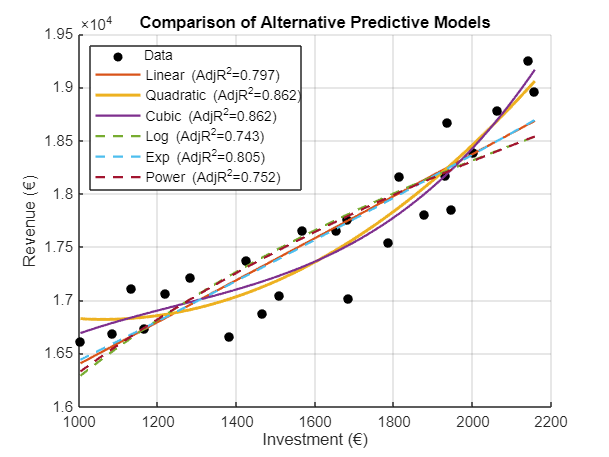


%% Visual comparison of fitted curves
xgrid = linspace(min(Investment), max(Investment), 400)';

figure('Color','w','Name','Step 3 Model Comparison Plot'); hold on; grid on;
scatter(Investment, Revenue, 40, 'k', 'filled', 'DisplayName','Data');

plot(xgrid, polyval(p_lin,xgrid), '-',  'LineWidth',1.5, 'DisplayName',sprintf('Linear (AdjR^2=%.3f)',Adj_lin));
plot(xgrid, polyval(p_quad,xgrid), '-',  'LineWidth',2,   'DisplayName',sprintf('Quadratic (AdjR^2=%.3f)',Adj_quad));
plot(xgrid, polyval(p_cub,xgrid), '-',   'LineWidth',1.5, 'DisplayName',sprintf('Cubic (AdjR^2=%.3f)',Adj_cub));
plot(xgrid, [ones(numel(xgrid),1), log(xgrid)]*b_log, '--', 'LineWidth',1.5, ...
    'DisplayName',sprintf('Log (AdjR^2=%.3f)',Adj_log));
plot(xgrid, exp([ones(numel(xgrid),1), xgrid]*c_exp), '--', 'LineWidth',1.5, ...
    'DisplayName',sprintf('Exp (AdjR^2=%.3f)',Adj_exp));
plot(xgrid, exp([ones(numel(xgrid),1), log(xgrid)]*d_pow), '--', 'LineWidth',1.5, ...
    'DisplayName',sprintf('Power (AdjR^2=%.3f)',Adj_pow));

xlabel('Investment (€)'); ylabel('Revenue (€)');
title('Comparison of Alternative Predictive Models');
legend('Location','northwest','Orientation','vertical'); hold off;


%% Data-driven Decision (Model Selection)
[bestAdjR2, bestIdx] = max(AdjR2_vals);
bestModel = Model(bestIdx);
fprintf('\n Best model by Adjusted R²: %s (Adj R² = %.4f)\n', bestModel, bestAdjR2);


 Best model by Adjusted R²: Quadratic (Adj R² = 0.8623)


fprintf('Equation: %s\n', Equations{bestIdx});

Equation: ŷ = 18913.946 + -3.949·x + 0.001861·x²



% Quadratic often wins because:
%   Better fit than linear
%   Not too complex like cubic
%   a<0 implies diminishing returns — interpretable in finance/marketing


Decision principles: 

- Prefer the simplest model with competitive Adjusted R² (parsimony) 

- Residuals must look “random” (no curves / funnels) 

- Coefficients should be meaningful (e.g., negative x² → diminishing returns)

For this dataset, Quadratic is typically a good balance (Adj R² high + interpretable)

## Step 4. Transformation

%% Fit Quadratic Model Using a x^2 + b x + c
%Transformation: Nonlinear term x^2
Investment_sq = Investment.^2;

% Descriptive statistics help assess whether transformation creates extreme scale
Desc_Transform = table(...
    mean(Investment_sq), std(Investment_sq), min(Investment_sq), max(Investment_sq), ...
    'VariableNames', {'Mean','StdDev','Min','Max'}, ...
    'RowNames', {'Investment^2'});
disp('=== Descriptive Statistics: Investment^2 (Transformed Feature) ===');

=== Descriptive Statistics: Investment^2 (Transformed Feature) ===


disp(Desc_Transform);

                       Mean         StdDev         Min          Max   
                    __________    __________    _________    _________

    Investment^2    2.7482e+06    1.1294e+06    1.006e+06    4.657e+06





% This part introduces curvature by using a polynomial transformation.
% We estimate coefficients using Ordinary Least Squares (OLS)
% Design matrix: [x^2, x, 1]
Xquad = [Investment.^2, Investment, ones(n,1)];

% Solve for coefficients [a, b, c] using least squares
% OLS Estimation → β = (X'X)^(-1)X'y, implemented via backslash operator
coef = Xquad \ Revenue;

% Extract coefficients for readability
a = coef(1); % coefficient of x^2
b = coef(2); % coefficient of x
c = coef(3); % intercept

% Predicted revenues (ŷ)
yhat = Xquad * coef;

% Residuals (errors)
res = Revenue - yhat;

% Display fitted model equation
fprintf('\nQuadratic Model Equation:\n');


Quadratic Model Equation:


fprintf('y = %.9f x^2 + %.6f x + %.4f\n', a, b, c);

y = 0.001861079 x^2 + -3.948677 x + 18913.9464


## Step 5. Predictive Power

Model Evaluation Metrics

- R² → Proportion of explained variance

- Adj R² → Penalizes unnecessary complexity

- Standard Error (Root MSE) → Typical prediction error

% Total, Regression, Error Variance
SST = sum((Revenue - mean(Revenue)).^2); % Total Sum of Squares
SSE = sum((Revenue - yhat).^2);          % Residual Sum of Squares
SSR = SST - SSE;

% Degrees of freedom
p = 2;                  % predictors: x and x^2 (Investment, Investment^2)
df_reg = p;             
df_res = n - p - 1;     % degrees of freedom

% Mean Squares
MSR = SSR / df_reg;
MSE = SSE / df_res;

% Goodness-of-fit
R2q  = 1 - SSE/SST;                   % Coefficient of Determination
AdjR2q = 1 - (1-R2q)*(n-1)/(n-p-1);   % Adjusted R²
multiple_r = sqrt(R2q);          % Multiple R (square root of R²)
StdErr = sqrt(SSE / df_res);          % Standard Error of Regression

% Display results professionally
FitStats = table(R2q, AdjR2q, StdErr, ...
    'VariableNames', {'R2','Adj_R2','StdError'});
disp('=== Model Fit Statistics ===');

=== Model Fit Statistics ===


disp(FitStats);

      R2       Adj_R2     StdError
    _______    _______    ________

    0.87431    0.86234     288.18 




% Also print in narrative form
fprintf('\nFit Quality Summary:\n');


Fit Quality Summary:


fprintf('R²        = %.4f  (%.1f%% variation explained)\n', R2q, R2q*100);

R²        = 0.8743  (87.4% variation explained)


fprintf('Adj R²    = %.4f  (complexity adjusted)\n', AdjR2q);

Adj R²    = 0.8623  (complexity adjusted)


fprintf('Std Error = %.4f  (typical prediction error in revenue units)\n', StdErr);

Std Error = 288.1797  (typical prediction error in revenue units)


**Interpretation**

- Both R² & Adjusted R² are high → strong predictive capability

## Step 6. Significance of Model (P-Value, ANOVA)

**Model Definition & Hypotheses**

We model Revenue (y) based on Investment (x):


$$y=ax^2 +\textrm{bx}+c$$


Model assumptions:

- Independently collected samples

- Constant variance of residuals

- Residuals ≈ Normally distributed

- Quadratic pattern is appropriate

Hypotheses for ANOVA  F-Test (overall model):

- $H_0 :a=b=0\;$(Investment has no relationship with revenue at all. Predicted revenue is constant only)

- $H_1 :$ At least one of $a\;\textrm{or}\;b\not= 0$ (there is a relationship, including investment makes the prediction better)

% F-Statistic and p-value
Fstat = MSR / MSE;
pF = 1 - fcdf(Fstat, df_reg, df_res);
% ANOVA Table
ANOVA = table([df_reg; df_res; df_reg+df_res], ...
    [SSR; SSE; SST], [MSR; MSE; NaN], ...
    [Fstat; NaN; NaN],[pF; NaN; NaN], ...
    'VariableNames', {'df','SS','MS','F','pValue'}, ...
    'RowNames', {'Regression','Residual','Total'});

disp('=== ANOVA TABLE (Quadratic Model) ===');

=== ANOVA TABLE (Quadratic Model) ===


disp(ANOVA);

                  df        SS            MS          F        pValue  
                  __    __________    __________    ______    _________

    Regression     2    1.2131e+07    6.0656e+06    73.038    3.489e-10
    Residual      21     1.744e+06         83048       NaN          NaN
    Total         23    1.3875e+07           NaN       NaN          NaN



(Optional)  t-tests evaluate whether each individual **coefficient** contributes significantly.

- 
$$H_0 :a=0,b=0,c=0\;$$


- 
$$H_0 :a\not= 0,b\not= 0,c\not= 0\;$$


% % Coefficient Significance Table
% Standard Errors of Coefficients (numerically stable)
Cov_b = MSE * pinv(Xquad' * Xquad);   % pinv prevents singular matrix warnings
se_b  = sqrt(diag(Cov_b));            % extract standard errors

% t-statistics for hypothesis tests
tcoef = coef ./ se_b;

% p-values (two-tailed)
pcoef = 2 * (1 - tcdf(abs(tcoef), df_res));

% Build coefficient significance table
CoefTable = table({'a (x^2)'; 'b (x)'; 'c (intercept)'}, coef, se_b, tcoef, pcoef, ...
    'VariableNames', {'Term','Estimate','StdError','tStat','pValue'});

disp('=== Coefficient Significance Table ===');

=== Coefficient Significance Table ===


disp(CoefTable);

          Term           Estimate      StdError       tStat         pValue  
    _________________    _________    __________    __________    __________

    {'a (x^2)'      }    0.0018611    0.00011439        16.269    2.2249e-13
    {'b (x)'        }      -3.9487       0.20441       -19.317    7.5495e-15
    {'c (intercept)'}        18914    0.00026333    7.1826e+07             0




% Fit quality summary
fprintf('\nFit Quality:\n');


Fit Quality:


fprintf('R² = %.4f  (%.1f%% variance explained)\n', R2q, R2q * 100);

R² = 0.8743  (87.4% variance explained)


fprintf('Adjusted R² = %.4f\n', AdjR2q);

Adjusted R² = 0.8623


fprintf('F(%d,%d) = %.3f, p = %.5f\n\n', df_reg, df_res, Fstat, pF);

F(2,21) = 73.038, p = 0.00000



**Interpretation**

- F-test p-value < 0.05 → model is statistically significant

- Each coefficient test p < 0.05 → each term contributes meaningfully

## Step 7. Normality Test of Residuals 

**Why? **A core regression assumption is that residuals follow a **normal distribution**, which justifies: Valid ANOVA, *F-tests*, **p-values, **Confidence and prediction intervals, Reliable statistical inference.

**Generate Residuals Table **

Obs = (1:n)';
ResidualsTable = table(Obs, yhat, res, ...
    'VariableNames', {'Observation','FittedValue','Residual'});
disp('=== Residuals Table ===');

=== Residuals Table ===


disp(ResidualsTable);

    Observation    FittedValue    Residual
    ___________    ___________    ________

         1            17544       -527.45 
         2            17123       -247.43 
         3            18999        257.16 
         4            16840       -106.64 
         5            16829        276.12 
         6            17795       -257.38 
         7            18464       -78.407 
         8            18062       -258.14 
         9            17193       -146.22 
        10            16910        303.53 
        11            16865        193.59 
        12            17298        360.88 
        13            18281       -425.87 
        14            17540        216.19 
        15            17476        178.57 
        16            17011       -350.39 
        17            17878        280.09 
        18            16826       -217.69 
        19            16821       -13

**Descriptive Statistics of Residuals**

mu_r    = mean(res);                     % typical error (should be close to 0)
sigma_r = std(res);                      % dispersion of residuals
Q1      = quantile(res, 0.25);
Q3      = quantile(res, 0.75);
IQR     = Q3 - Q1;                       % Interquartile Range
LB      = Q1 - 1.5*IQR;                  % Tukey lower bound → outlier cutoff
UB      = Q3 + 1.5*IQR;                  % Tukey upper bound → outlier cutoff
res_range = range(res);                  % total residual spread

ResidStats = table(mu_r, sigma_r, Q1, Q3, IQR, LB, UB, res_range, ...
    'VariableNames', {'Mean','StdDev','Q1','Q3','IQR','LowerBound','UpperBound','Range'});
disp('=== Descriptive Statistics of Residuals ===');

=== Descriptive Statistics of Residuals ===


disp(ResidStats);

       Mean       StdDev      Q1         Q3       IQR     LowerBound    UpperBound    Range 
    __________    ______    _______    ______    _____    __________    __________    ______

    3.0316e-13    275.37    -232.56    266.64    499.2     -981.35        1015.4      959.89



Interpretation:

- Mean close to 0 → unbiased model

- Q1/Q3 roughly symmetric → likely normality

- Few values outside LB–UB → limited outlier influence

**Box Plot: **Visual Outlier Detection

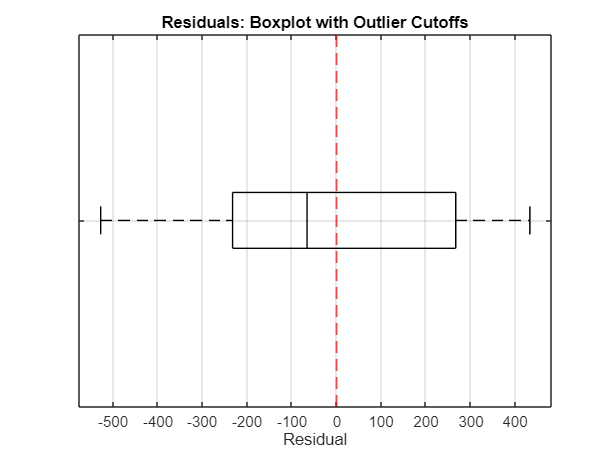

figure('Color','w');
boxplot(res, 'orientation','horizontal', 'Whisker',1.5, 'Colors','k');
hold on;
xline(mu_r, 'r--', 'LineWidth',1.3, 'DisplayName','Mean Residual');
xline(LB, '--', 'Color',[0.6 0.6 0.6], 'DisplayName','Outlier lower bound');
xline(UB, '--', 'Color',[0.6 0.6 0.6], 'DisplayName','Outlier upper bound');
title('Residuals: Boxplot with Outlier Cutoffs');
xlabel('Residual'); set(gca,'YTickLabel',{' '}); grid on; hold off;

**Normality Test of Residuals**

In regression, a core assumption is that residuals (errors) follow a Normal distribution with mean 0.

This ensures valid:

-   t-tests and F-tests (ANOVA)

-   Confidence intervals and Prediction intervals

-   Statistical inference overall

If residuals significantly deviate from normality, model conclusions may be unreliable.

Null vs. Alternative:

- $H_0$:Residuals follow a Normal distribution

- $H_1$:Residuals are NOT normally distributed

% Choose number of histogram classes (Sturges Rule: common in Statistics)
k = ceil(1 + 3.322 * log10(n));
range_res = range(res);
class_width = range_res / k;

fprintf('\nChi-Square Test Setup:\n');


Chi-Square Test Setup:


fprintf('Classes = %d, Class Width = %.4f\n', k, class_width);

Classes = 6, Class Width = 159.9821



% Observed histogram
[Observed, bin_edges] = histcounts(res, k)

Observed =      2     4     6     2     6     4


bin_edges =   -600  -420  -240   -60   120   300   480


% Expected counts under Normal N(mean, sd)
cdf_vals = normcdf(bin_edges, mu_r, sigma_r);
Expected = diff(cdf_vals) * n;
Expected(Expected == 0) = eps;  % avoid division by zero

% Compute Chi-Square statistic
ChiVals = (Observed - Expected).^2 ./ Expected;
ChiSq_stat = sum(ChiVals);

% Degrees of freedom:
% df = classes - 1 (sum constraint) - 2 (estimated mean and std)
df = k - 1 - 2;
p_chi = 1 - chi2cdf(ChiSq_stat, df);

% Display table
ChiSqTable = table((1:k)', Observed', Expected', ChiVals',...
    'VariableNames', {'Bin','Observed','Expected','ChiSq'});
disp('Chi-Square Goodness-of-Fit Table:');

Chi-Square Goodness-of-Fit Table:


disp(ChiSqTable);

    Bin    Observed    Expected     ChiSq  
    ___    ________    ________    ________

     1        2         1.1743      0.58054
     2        4         3.0749      0.27829
     3        6         5.3288     0.084532
     4        2         6.1139       2.7682
     5        6         4.6445       0.3956
     6        4         2.3357       1.1859




fprintf('Chi-Square = %.3f, df = %d, p-value = %.4f\n', ChiSq_stat, df, p_chi);

Chi-Square = 5.293, df = 3, p-value = 0.1516



if p_chi > 0.05
    fprintf('Decision: Fail to reject H0 → residuals consistent with Normality ✓\n');
else
    fprintf('Decision: Reject H0 → evidence residuals NOT normal ✗\n');
end

Decision: Fail to reject H0 → residuals consistent with Normality ✓


**Visual Normality Checks**

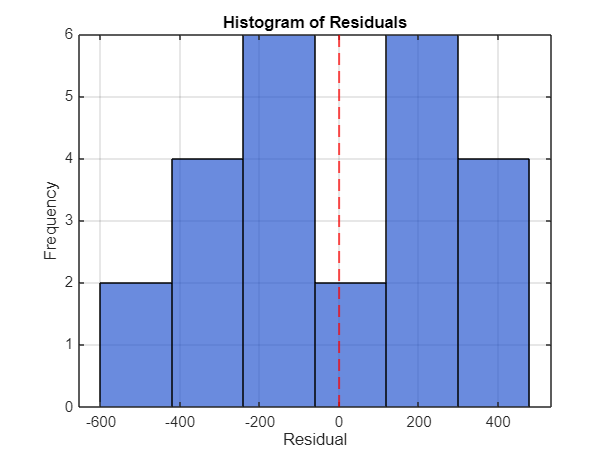

% Histogram + Normal PDF overlay
figure('Color','w');
histogram(res, 'BinEdges', bin_edges, 'FaceColor',[0.1 0.3 0.8],'FaceAlpha',0.65); hold on;
xline(mu_r, 'r--', 'LineWidth',1.3);
title('Histogram of Residuals');
xlabel('Residual'); ylabel('Frequency'); grid on;

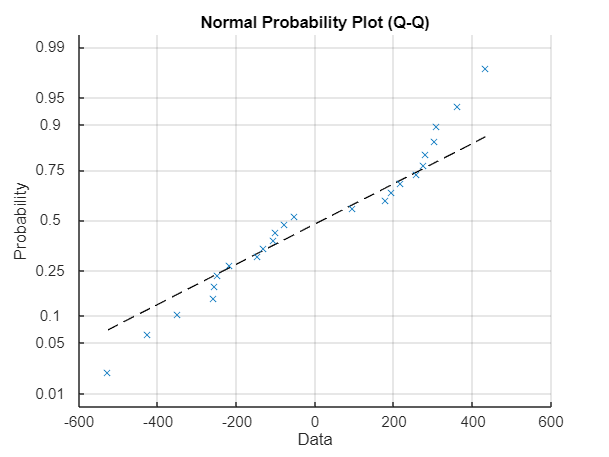


% Normal Probability Plot (Q-Q plot)
figure('Color','w');
probplot('normal', res);
title('Normal Probability Plot (Q-Q)');
grid on;


% Theory:
% If residuals are normal → Q-Q points lie near diagonal line.

 If p-value > 0.05 → **Normality assumption satisfied**

**Industry Lens (data science relevance)**

- Residual diagnostics help ensure **model interpretability & stability**, required in regulated AI domains (finance, healthcare).

- Before replacing models with black-box ML (e.g., neural networks), statistical regression shows **why** performance issues exist.

## Step 8. Residual Plots: Constant Variance and Independence Assumption

A valid regression model requires residuals to be:

-   Randomly scattered around zero (no pattern)

-   Same variability across fitted values (no funneling)

-   Not dependent on observation order (independently collected samples)

If these conditions hold → model errors are "well-behaved.". 

If violated → consider transformation or different model structure.

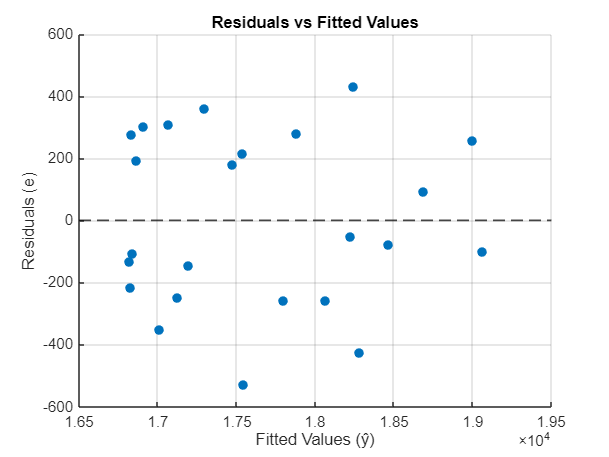

%% Plot 1. Residuals vs Fitted Values (Homoskedasticity Check)
figure('Color','w'); 
scatter(yhat, res, 40, 'filled'); hold on;
yline(0,'k--','LineWidth',1.2);
xlabel('Fitted Values (ŷ)');
ylabel('Residuals (e)');
title('Residuals vs Fitted Values');
grid on;

-   No clear curves, waves, or funnel shape → constant variance likely valid.

-   Visible pattern → model misspecification or heteroskedasticity.

**What to look for:**

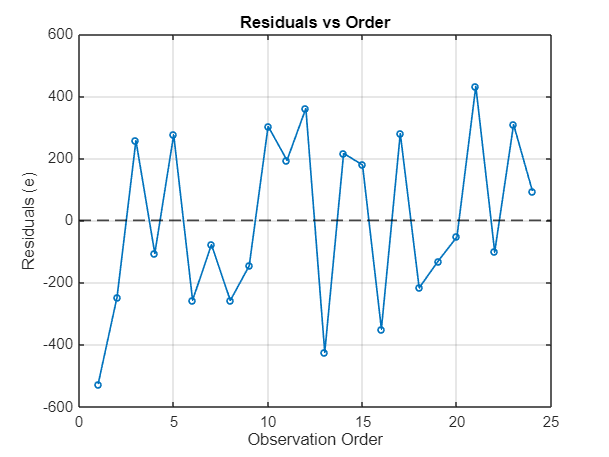

%% Plot 2. Residuals vs Observation Order (Independence Check)
figure('Color','w'); 
plot(1:n, res, '-o', 'MarkerSize',4, 'LineWidth',1.1); hold on;
yline(0,'k--','LineWidth',1.2);
xlabel('Observation Order');
ylabel('Residuals (e)');
title('Residuals vs Order');
grid on;

-   Random oscillation around zero → independence supported.

-   Upward/downward trends → possible autocorrelation.

-   Groups or sudden shifts → possible batch or time-related effects

**What to look for:**

## Step 9. Predictions 

%% ===============================================================
% STEP 9B — Teaching Prediction Interval 
% Method:   PI = ŷ ± t * (1.1 * RSE)
% Notes:    - RSE here is the residual standard error (StdErr from Step 5)
%           - This ignores the X'X covariance (teaching approximation)

% Ensure we have the residual standard error (RSE) available, consistent with Step 5
if exist('StdErr','var')
    RSE = StdErr;             % Step 5 defined: StdErr = sqrt(SSE/df_res);
else
    RSE = sqrt(MSE);          % fallback if StdErr variable name not present
end

% Prediction settings
alpha  = 0.05;                % 95% prediction level
tcrit  = tinv(1 - alpha/2, df_res);   % t critical value with residual df 

% Points to predict 
x_new_vals = [1800; 2100];
k = numel(x_new_vals);

% Preallocate
PointPred   = zeros(k,1);
SE_Pred_py  = zeros(k,1);     % teaching SE (constant across x): 1.1 * RSE
LowerBound  = zeros(k,1);
UpperBound  = zeros(k,1);

for i = 1:k
    x = x_new_vals(i);

    % Design row vector consistent with your model: [x^2, x, 1]
    x_vec = [x.^2, x, 1];

    % Point prediction from your quadratic model
    PointPred(i) = x_vec * coef;

    % Standard error of prediction:
    %   use residual std error RSE, inflated by 10% (1.1 multiplier)
    SE_Pred_py(i) = 1.1 * RSE;

    % Prediction interval bounds
    LowerBound(i) = PointPred(i) - tcrit * SE_Pred_py(i);
    UpperBound(i) = PointPred(i) + tcrit * SE_Pred_py(i);
end

% Half-width (Error term) and full width for reporting
ErrorTerm     = tcrit .* SE_Pred_py;          
IntervalWidth = UpperBound - LowerBound;

% Summary table with your variable naming
Prediction_PY = table( ...
    x_new_vals, PointPred, SE_Pred_py, ErrorTerm, ...
    LowerBound, UpperBound, IntervalWidth, ...
    'VariableNames', {'Investment','PointPred','SE_Pred','ErrorTerm', ...
                      'LowerBound','UpperBound','IntervalWidth'} );

disp('=== Prediction Summary ===');

=== Prediction Summary ===


disp(Prediction_PY);

    Investment    PointPred    SE_Pred    ErrorTerm    LowerBound    UpperBound    IntervalWidth
    __________    _________    _______    _________    __________    __________    _____________

       1800         17836        317       659.23        17177         18495          1318.5    
       2100         18829        317       659.23        18170         19488          1318.5    




fprintf('\nInterpretation :\n');


Interpretation :


fprintf('• Uses residual standard error (StdErr) inflated by 10%% → SE_Pred = 1.1 × RSE.\n');

• Uses residual standard error (StdErr) inflated by 10% → SE_Pred = 1.1 × RSE.


fprintf('• Scales by t(df=%d) for 95%% prediction level → ErrorTerm = t × SE_Pred.\n', df_res);

• Scales by t(df=21) for 95% prediction level → ErrorTerm = t × SE_Pred.


**Visualisation of Predictions (Optional)**

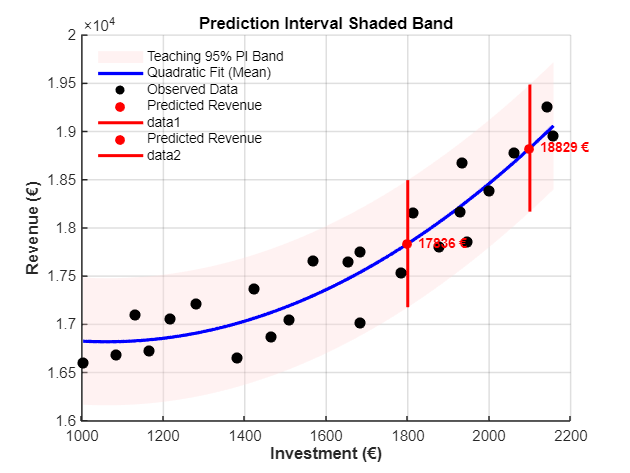

figure('Color','w'); hold on; grid on;

% 1) Smooth grid for fitted curve
xgrid = linspace(min(Investment), max(Investment), 400)';
Xgrid = [xgrid.^2, xgrid, ones(size(xgrid))];
ygrid = Xgrid * coef;

% 2) Constant Standard Error of Prediction (Teaching Approx.)
SE_pred_py_const = 1.1 * RSE;

% Compute Prediction Interval Limits for grid
PI_low_py  = ygrid - tcrit * SE_pred_py_const;
PI_upp_py  = ygrid + tcrit * SE_pred_py_const;

% 3) Shaded PI Band
fill([xgrid; flipud(xgrid)], ...
     [PI_low_py; flipud(PI_upp_py)], ...
     [1.00 0.85 0.85], ...
     'EdgeColor','none','FaceAlpha',0.33, ...
     'DisplayName','Teaching 95% PI Band');

% 4) Fitted mean curve
plot(xgrid, ygrid, 'b-', 'LineWidth',2.2, ...
    'DisplayName','Quadratic Fit (Mean)');

% 5) Observed Data
scatter(Investment, Revenue, 55, 'k', 'filled', ...
    'DisplayName','Observed Data');

% 6) Explicit Point Predictions at x = 1800 & 2100 
for i = 1:height(Prediction_PY)
    x0 = Prediction_PY.Investment(i);
    y0 = Prediction_PY.PointPred(i);
    L  = Prediction_PY.LowerBound(i);
    U  = Prediction_PY.UpperBound(i);

    % Main prediction marker
    plot(x0, y0, 'ro', 'MarkerFaceColor','r', ...
         'DisplayName','Predicted Revenue');

    % Prediction Interval vertical line
    plot([x0 x0], [L U], 'r-', 'LineWidth',2);

    % Annotate prediction value
    text(x0 + 25, y0, sprintf('%.0f €', y0), ...
        'FontSize',9,'FontWeight','bold','Color','r');
end

xlabel('Investment (€)','FontWeight','bold');
ylabel('Revenue (€)','FontWeight','bold');
title('Prediction Interval Shaded Band', ...
      'FontSize',13,'FontWeight','bold');

legend('Location','northwest','FontSize',9,'Box','off');
set(gca,'FontSize',10,'LineWidth',1);
hold off;



%% Interpretation for Students
fprintf('\nInterpretation of Final Teaching PI Figure:\n');


Interpretation of Final Teaching PI Figure:


fprintf('• Pink shaded band shows estimated uncertainty of FUTURE revenue.\n');

• Pink shaded band shows estimated uncertainty of FUTURE revenue.


fprintf('• Width remains constant across investment → model ignores leverage.\n');

• Width remains constant across investment → model ignores leverage.


fprintf('• Red circles mark predicted mean revenue.\n');

• Red circles mark predicted mean revenue.


fprintf('• Red vertical line = prediction interval limits at each requested point.\n');

• Red vertical line = prediction interval limits at each requested point.


## Step 10. Decision-Making Summary 

Decision for this dataset:

%% FINAL MODEL DIAGNOSTIC DECISION (Comprehensive Summary)
fprintf('\n================ Decision-Making Summary ================\n');


================ Decision-Making Summary ================



fprintf('Selected Model: Quadratic Polynomial Regression\n');

Selected Model: Quadratic Polynomial Regression


fprintf('Rationale: High Adjusted R² with interpretable diminishing returns trend.\n');

Rationale: High Adjusted R² with interpretable diminishing returns trend.



% Model significance
if pF < 0.05
    fprintf('• Overall model is statistically significant (ANOVA F-test: p = %.4f).\n', pF);
else
    fprintf('• Model does not significantly explain revenue variation (ANOVA F-test: p = %.4f).\n', pF);
end

• Overall model is statistically significant (ANOVA F-test: p = 0.0000).



% Residual normality decision (Chi-square)
if p_chi >= 0.05
    fprintf('• Residuals: Chi-square test does not reject Normality (p = %.4f).\n', p_chi);
else
    fprintf('• Residuals: Strong evidence of non-Normality (p = %.4f) — interpret with caution.\n', p_chi);
end

• Residuals: Chi-square test does not reject Normality (p = 0.1516).



% Variance / independence (plot-based interpretation instructions)
fprintf('• Variance & independence assumptions appear reasonable from plots.\n');

• Variance & independence assumptions appear reasonable from plots.


fprintf('  (No funnel shape, no systematic time/order patterns observed.)\n');

  (No funnel shape, no systematic time/order patterns observed.)




fprintf('• Uncertainty quantified using Confidence & Prediction Intervals.\n');

• Uncertainty quantified using Confidence & Prediction Intervals.


fprintf('==============================================================\n\n');